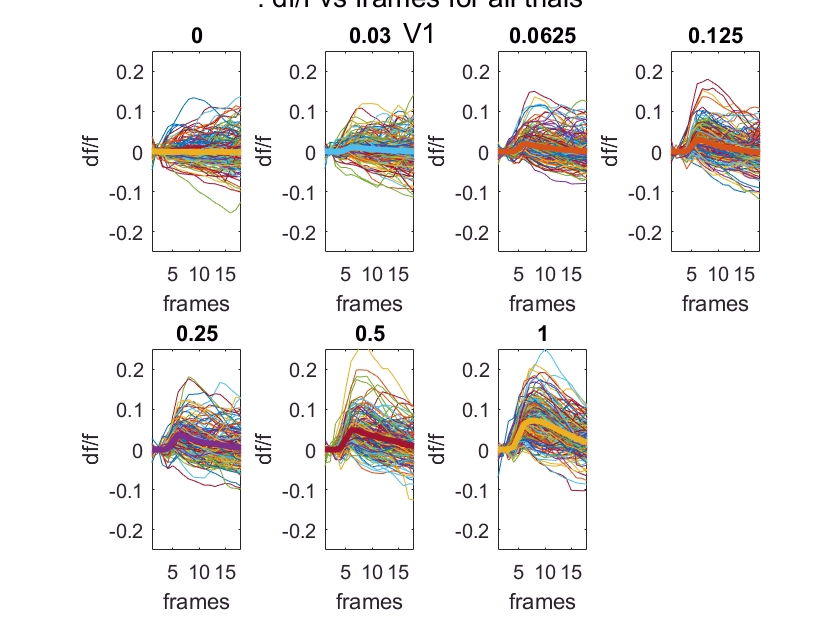

state = 'hiRun';
visArea = 1;

% for each session
clear n
for n = 1:nGroup

    % EXTRACT list of stim params & stim conditions in order of trial 
    [durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthPTSdfof = groupPTSdfof{1,n};
    nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
    nthBaselineIdx = groupBaselineIdx{1,n};
    
    if state == 'loRun'
    
        % EXTRACT loRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxStatTrials{1,n}; 
        
    end 
    
    if state == 'hiRun'
    
        % EXTRACT hiRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxRunTrials{1,n}; 
        
    end
    
    if state == 'loPup'
    
        % EXTRACT hiRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxSmallPupilTrials{1,n}; 
        
    end
    
    if state == 'hiPup'
    
        % EXTRACT hiRun TRIAL INDICIES
        nthIdxBehStateTrials = groupIdxLargePupilTrials{1,n}; 
        
    end
    
    % for each duration
    clear d
    for d = durat % at each duration
            
        % for each area
        clear i
        for i = visArea % can be 1 area or length of xPts

        figure % make one figure for all subplots
        clear titleText
        titleText = ': df/f vs frames for all trials'; % making char variables for sprintf/title later
        %suptitle(sprintf('%s', date, subjName, titleText, reigons{i}));
        suptitle(sprintf('%s\n', titleText, reigons{i}));
            
            % for each contrast
            clear c
            for c = cont 

                % SELECT TRIALS for specified pupil state & stim params
                [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,nthIdxBehStateTrials);

                clear recomboOnePtAllFramesAllTrialMinusMeanBase
                clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

                % collect all trials over all frames for the ith point
                clear onePtAllFramesAndTrials % new var each point
                onePtAllFramesAndTrials = squeeze(nthPTSdfof(i,:,idxTrials)); 
                onePtAllFramesAndTrials = onePtAllFramesAndTrials';

                % for every trace, subtract the baseline value at that point from each frame value
                clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
                    % getting TRIAL VECTOR
                    clear onePtAllFramesOneTrial % make new var for each trial
                    % index into each trace/vector & save as variable
                    onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);

                    % getting MEAN BASEline VALUE for each TRIAL
                    clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                    % collect 4 baseline frames for tr-th ith trial
                    allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,nthBaselineIdx);

                    clear mean4baseFramesOnePtOneTrial
                    % get mean value of baseline values for ith point
                    mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                    mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);

                    % BASEline CORRECTion of TRIAL VECTOR
                    % new baseline-corrected trace for each trial
                    onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;

                    % collect CORRECTed TRIAL VECTORS in matrix
                    % (only clear this outside the loop for each point)
                    recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
                    % PLOT
                    clear x_axis
                    x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
                    % plot one baseline corrected trace at a time
                    subplot(2,4,c) % make a subplot
                    plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)

                    hold on % hold for next trial
                
                end % end tr loop

                hold on % hold for plotting mean over subplot

                % get mean baselined trace across all trials
                meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials

                plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
                title(uniqueContrasts(c))

                ylim([-0.25 0.25]) 
                xlim([1 length(x_axis)])
                ylabel('df/f')
                xlabel('frames')

                ax = gca;
               % x.XTick = [1:1:length(x_axis)];
       
            end % end c loop
        
        end % end d loop
        
    end %end i loop
                
end % end n loop

% interp stuff from a while ago (before finsihed making fucniton i think)


% INTERP - LOCO

% loop vars for interp, calc C50, & plot
% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)
visArea = 1:length(groupRoundXpts{1,n})

for d = durat
    
    clear lo_yi_interpedConsCurve_allPts{}
    clear lo_xi_isDf_higherRes_allPts{} 
    clear lo_C50_allPts
    clear lo_df_at_C50_allPts
    
    clear hi_yi_interpedConsCurve_allPts{}
    clear hi_xi_isDf_higherRes_allPts{} 
    clear hi_C50_allPts
    clear hi_df_at_C50_allPts
    
    for i = visArea

        % INTERP - LO beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_lo = loRun_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;
        % resolution of interpolation 
        higherRes = 1/1000; 
        lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);
        
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        lo_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_lo_Res_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
        % use index to find associated interped CON value
        lo_C50 = lo_yi_interpedConsCurve(1,idx_df_lo_Res_aboveC50);
        
        % COLLECT LO VARS to plot
        lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
        lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
        lo_C50_allPts(i,:) = lo_C50;
        lo_df_at_C50_allPts(i,:) = lo_df_at_C50;
        
        % INTERP - HI beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_hi = hiRun_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_hi;
        % resolution of interpolation 
        higherRes = 1/1000; 
        hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-min(ith_mnCRF_acrossSess_AllDurAllPts_hi);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        hi_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
        % use index to find associated interped cCON value
        hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);
        
        % COLLECT VARS to plot
        hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
        hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
        hi_C50_allPts(i,:) = hi_C50;
        hi_df_at_C50_allPts(i,:) = hi_df_at_C50;

    end % end i loop
    
end % end d loop

    % PLOT INTERP + CRF, LOCO, BOTH beh STATES one FIG

% for FIGURE/Axes
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];

%x_axis = [1:length(uniqueContrasts)];
xMax = max(uniqueContrasts);
xMin = min(uniqueContrasts);
xLimit = [xMin xMax];
xt=[0 0.03 0.06 0.12 0.25 0.5 1];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
%xtl={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'};

stateLegend = {'stat','run'};

figure

for i = visArea % leave out control area
    
    subplot(2,4,i)
    
    if nGroup == 1
            
        plot(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    else
        
        errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    end
    
    ylim(yLimit) 
    xlim(xLimit)
    ylabel('df/f')
    xlabel('contrast (%)')                
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);
    set(gca,'YTick',yt)
    
    axis square

end 

% INTERP - PUPIL

% loop vars for interp, calc C50, & plot
% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)
visArea = 1:length(groupRoundXpts{1,n})

for d = durat
    
    clear lo_yi_interpedConsCurve_allPts{}
    clear lo_xi_isDf_higherRes_allPts{} 
    clear lo_C50_allPts
    clear lo_df_at_C50_allPts
    
    clear hi_yi_interpedConsCurve_allPts{}
    clear hi_xi_isDf_higherRes_allPts{} 
    clear hi_C50_allPts
    clear hi_df_at_C50_allPts
    
    for i = visArea

        % INTERP - LO beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_lo = loPup_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;
        % resolution of interpolation 
        higherRes = 1/1000; 
        lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);
        
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        lo_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_lo_Res_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
        % use index to find associated interped CON value
        lo_C50 = lo_yi_interpedConsCurve(1,idx_df_lo_Res_aboveC50);
        
        % COLLECT LO VARS to plot
        lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
        lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
        lo_C50_allPts(i,:) = lo_C50;
        lo_df_at_C50_allPts(i,:) = lo_df_at_C50;
        
        % INTERP - HI beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_hi = hiPup_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_hi;
        % resolution of interpolation 
        higherRes = 1/1000; 
        hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-min(ith_mnCRF_acrossSess_AllDurAllPts_hi);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        hi_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-halfOf_range;
        
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
        % use index to find associated interped cCON value
        hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);
        
        % COLLECT VARS to plot
        hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
        hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
        hi_C50_allPts(i,:) = hi_C50;
        hi_df_at_C50_allPts(i,:) = hi_df_at_C50;

    end % end i loop
    
end % end d loop

% PLOT INTERP + CRF, PUPIL, BOTH beh STATES one FIG

% for FIGURE/Axes
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];

%x_axis = [1:length(uniqueContrasts)];
xMax = max(uniqueContrasts);
xMin = min(uniqueContrasts);
xLimit = [xMin xMax];
xt=[0 0.03 0.06 0.12 0.25 0.5 1];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
%xtl={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'};

stateLegend = {'stat','run'};

figure

for i = visArea % leave out control area
    
    subplot(2,4,i)
    
    if nGroup == 1
            
        plot(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    else
        
        errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'b')
        hold on 
        plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
        hold on 
        plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
        
        hold on
       
        errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
        hold on 
        plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
        hold on 
        plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    end
    
    ylim(yLimit) 
    xlim(xLimit)
    ylabel('df/f')
    xlabel('contrast (%)')                
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);
    set(gca,'YTick',yt)
    
    axis square

end 

durat = 1
%visArea = 1
visArea = 1:length(groupRoundXpts{1,n})
%sess = 1
sess = 1:nGroup

global durat 
global visArea 
global sess 

global uniqueContrasts

[lo_yi_interpedConsCurve_allPtsAllSess,lo_xi_isDf_higherRes_allPtsAllSess,lo_C50_allPtsAllSess,lo_df_at_C50_allPtsAllSess,hi_yi_interpedConsCurve_allPtsAllSess,hi_xi_isDf_higherRes_allPtsAllSess,hi_C50_allPtsAllSess,hi_df_at_C50_allPtsAllSess] = makeC50_test(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF);
% the c50 output vars are pts x column w/df values at c50 x sess (probs better dimsional arrangement for this...)
lo_C50_allPtsAllSess = squeeze(lo_C50_allPtsAllSess);
hi_C50_allPtsAllSess = squeeze(hi_C50_allPtsAllSess);
% w/squeeze they are points x sess
size(lo_C50_allPtsAllSess)
size(hi_C50_allPtsAllSess)
